Plot each scan and then fit lines and circles to it

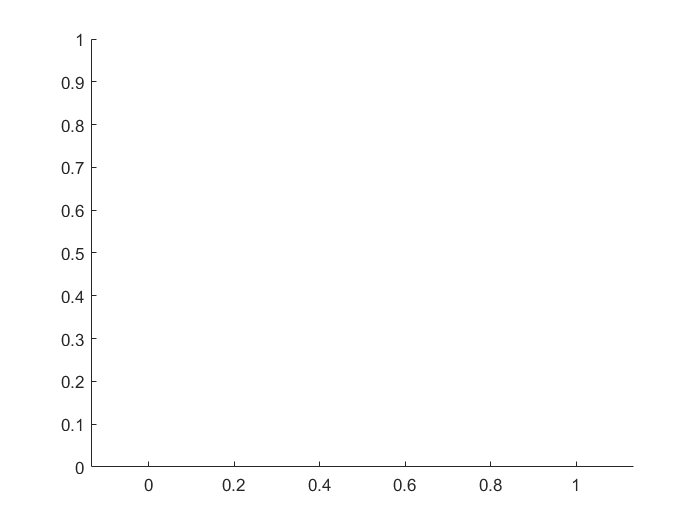

% load something
bob_radius = 0.25;
clf;
hold on; axis equal;


% assume scans is a matrix containing each scan
for i=1:size(scans)
    current_scan_points = scans(i)
    plot(current_scan_points(:,1), current_scan_points(:,2)); 
end

Unrecognized function or variable 'scans'.


[line_inliers, circle_inliers, circle_center, end_points] = detectObjects(all_points, bob_radius);
% plot(line_inliers(:,1), line_inliers(:,2), 'rs','DisplayName','Line Inliers');
% plot(circle_inliers(:,1), circle_inliers(:,2), 'bs');

% plot fitted lines
for i=1:size(end_points,1)
    plot([end_points(i,1) end_points(i,2)],[end_points(i,3) end_points(i,4)],'r','LineWidth',3)
end

% plot circle equation
syms x y
circle_equation_explicit = (x-circle_center(1))^2 + (y-circle_center(2))^2 == bob_radius^2;
fimplicit(circle_equation_explicit,[-4*pi 4*pi],'b','LineWidth',3, 'DisplayName','Fitted BoB'); axis equal;

title("Map of Gauntlet Using LIDAR, Obstacles and BoB Fitted with RANSAC")
xlabel("x (m)")
ylabel("y (m)")
legend show
hold off

Load encoder data and calculate trajectory of Neato 

data = readtable("encoder_data.csv", "Delimiter", ",");
data_size = size(data, 1);

% create empty wheel velocities, speed and angular velocity matrices
v_left_actual = zeros(1, data_size);
v_right_actual = zeros(1, data_size);
speed_actual = zeros(1, data_size);
angular_velocity_actual = zeros(1, data_size);

% calculate wheel velocities, speed and angular velocity from encoder data
for i=1:(data_size - 1)
    v_left_actual(i) = (data.encoderLeft(i+1) - data.encoderLeft(i))/(data.time(i+1) - data.time(i));
    v_right_actual(i) = (data.encoderRight(i+1) - data.encoderRight(i))/(data.time(i+1) - data.time(i));
    speed_actual(i) = (v_left_actual(i) + v_right_actual(i))/2;
    angular_velocity_actual(i) = (v_right_actual(i) - v_left_actual(i))/d;
end

% create empty theta and position matrices
theta = zeros(data_size, 1);
r_actual = zeros(data_size, 2);

% initial values
heading  = [1 0];
theta(1) = atan2(heading(2), heading(1)); % calculate initial theta from initial orientation
r_actual(1,:) = [0 0]; 
total_distance = 0;

% calculate actual heading and position at each point
for i=2:data_size
    delta_time = data.time(i) - data.time(i-1);
    theta(i) = theta(i-1) + angular_velocity_actual(i-1) * delta_time;
    r_actual(i, 1) = r_actual(i-1,1) + speed_actual(i-1) * cos(theta(i)) * delta_time;
    r_actual(i, 2) = r_actual(i-1,2) + speed_actual(i-1) * sin(theta(i)) * delta_time;
    
    % use sqrt((x2-x1)^2 + (y2-y1)^2) to calculate the distance the neato
    % just traveled
    current_distance = sqrt((r_actual(i, 1) -  r_actual(i-1,1))^2 + (r_actual(i, 2) -  r_actual(i-1,2))^2)
    % add to total distance
    total_distance = total_distance + current_distance;
end
total_distance

Plot path that robot took

hold on; axis equal;

% plot map of gauntlet based on above
% yes this is copied from above lol
% plot fitted lines
for i=1:size(end_points,1)
    plot([end_points(i,1) end_points(i,2)],[end_points(i,3) end_points(i,4)],'r','LineWidth',2)
end

% plot circle equation
syms x y
circle_equation_explicit = (x-circle_center(1))^2 + (y-circle_center(2))^2 == bob_radius^2;
fimplicit(circle_equation_explicit,[-4*pi 4*pi],'b','LineWidth',3, 'DisplayName','BoB'); axis equal;

% plot intended gradient descent

% plot actual path
plot(r_actual(:,1), r_actual(:,2), 'r--')

title("Intended Gradient Descent and Actual Robot Path")
xlabel("x (m)")
ylabel("y (m)")
legend show
hold off